% (3*x^2*y+sin(x))*dx+(x^3-cos(y))*dy=0

clear
% 1)
% y'=-(3*x^2*y+sin(x))/(x^3-cos(y)
syms x y(x)
eqn=diff(y(x))==-(3*x^2*y+sin(x))/(x^3-cos(y))

$$eqn(x) = \frac{\partial }{\partial x}y\left(x\right)=\frac{\sin\left(x\right)+3\,x^{2}\,y\left(x\right)}{\cos\left(y\left(x\right)\right)-x^{3}}$$

ySol=dsolve(eqn)

$$ySol = \mathrm{solve}\left(\sin\left(y\right)-x^{3}\,y=-C_{6}-\cos\left(x\right),y\right)$$

% solve(- y*x^3 + sin(y) == - C6 - cos(x), y)
% - y*x^3 + sin(y) == - C6 - cos(x)

% 2)
syms x y
P(x,y)=3*x^2*y+sin(x)

$$P(x, y) = \sin\left(x\right)+3\,x^{2}\,y$$

Q(x,y)=x^3-cos(y)

$$Q(x, y) = x^{3}-\cos\left(y\right)$$

f=diff(P,y)-diff(Q,x)

$$f(x, y) = 0$$

% dPy==dQx

% U(x,y)
% dUx=P, dUy=Q
syms C(y)
U=int(P(x,y),x)+C(y)

$$U = C\left(y\right)-\cos\left(x\right)+x^{3}\,y$$

% C(y) - cos(x) + x^3*y
dUy=diff(U,y)

$$dUy = \frac{\partial }{\partial y}C\left(y\right)+x^{3}$$

% x^3 + diff(C(y), y)
dCy=simplify(dUy-Q)

$$dCy(x, y) = \frac{\partial }{\partial y}C\left(y\right)+\cos\left(y\right)$$

% diff(C(y), y) + cos(y)
C(y)=int(-cos(y),y)

$$C(y) = -\sin\left(y\right)$$

% -sin(y)
% cos(x) - x^3*y + sin(y) = C1

% 3)
x0=0;y0=0;
U=simplify(int(P(x,y),x,x0,x)+int(subs(Q(x,y),x,x0),y,y0,y))

$$U = x^{3}\,y-\sin\left(y\right)-\cos\left(x\right)+1$$

syms C
eq2=1-U==C

$$eq2 = \cos\left(x\right)+\sin\left(y\right)-x^{3}\,y=C$$

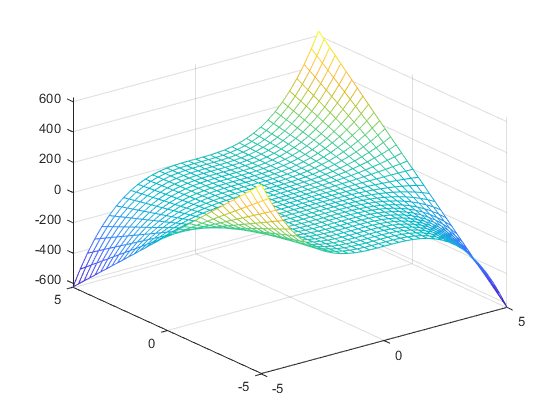

fmesh(U)